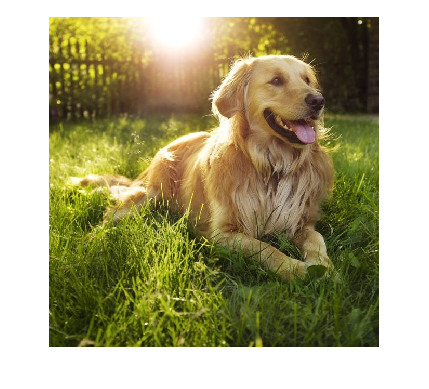


img=imread("squaredog.jpg");
imshow(img);

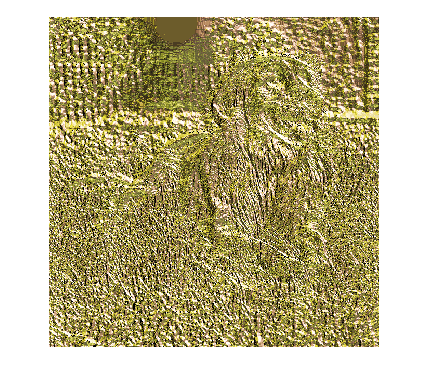

img = im2double(img);
norm = imresize(imread("normal.png"),[635,635]);

fdx = double(norm(:,:,1));
fdy = double(norm(:,:,2));



[y, x]=ndgrid(1:size(img,1),1:size(img,2));


R = interp2(double(img(:,:,1)),fdx(:,:),fdy(:,:));
R(isnan(R))=0;
G = interp2(double(img(:,:,2)),fdx(:,:),fdy(:,:));
G(isnan(G))=0;
B = interp2(double(img(:,:,3)),fdx(:,:),fdy(:,:));
B(isnan(B))=0;

edited = cat(3,R,G,B);

imshow(edited);



%montage({img, edited});